### Spatial and Temporal Plots for $\epsilon$

% Spacial variations

L = 0.01;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 1e2;
vp = 0.5e8;
z = linspace(0, L, N_L);

E = omega/vp;
Gamma = 0.5*exp(-E.*1j.*z);
dGamma = 0.5*(-1j.*E)*exp(-E.*1j.*z);

% find a and b
a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

% find eps(z)
epsz = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2)

epsz = 1.0e-09 *

   0.1257 + 0.0000i   0.0825 - 0.0710i   0.0238 - 0.0735i  -0.0028 - 0.0517i  -0.0101 - 0.0336i  -0.0105 - 0.0221i  -0.0091 - 0.0151i  -0.0074 - 0.0108i  -0.0059 - 0.0080i  -0.0047 - 0.0061i  -0.0037 - 0.0048i  -0.0029 - 0.0038i  -0.0022 - 0.0031i  -0.0017 - 0.0026i  -0.0012 - 0.0021i  -0.0009 - 0.0018i  -0.0006 - 0.0015i  -0.0003 - 0.0012i  -0.0002 - 0.0010i  -0.0000 - 0.0008i   0.0001 - 0.0007i   0.0002 - 0.0005i   0.0003 - 0.0004i   0.0003 - 0.0002i   0.0004 - 0.0001i   0.0004 + 0.0000i   0.0004 + 0.0002i   0.0003 + 0.0003i   0.0003 + 0.0004i   0.0002 + 0.0006i   0.0001 + 0.0008i  -0.0001 + 0.0009i  -0.0002 + 0.0011i  -0.0005 + 0.0014i  -0.0007 + 0.0016i  -0.0010 + 0.0019i  -0.0014 + 0.0023i  -0.0019 + 0.0028i  -0.0025 + 0.0035i  -0.0032 + 0.0043i  -0.0041 + 0.0054i  -0.0053 + 0.0070i  -0.0067 + 0.0093i  -0.0083 + 0.0127i  -0.0099 + 0.0182i  -0.0107 + 0.0271i  -0.0078 + 0.0417i   0.0069 + 0.0629i   0.0496 + 0.0787i   0.1129 + 0.0436i


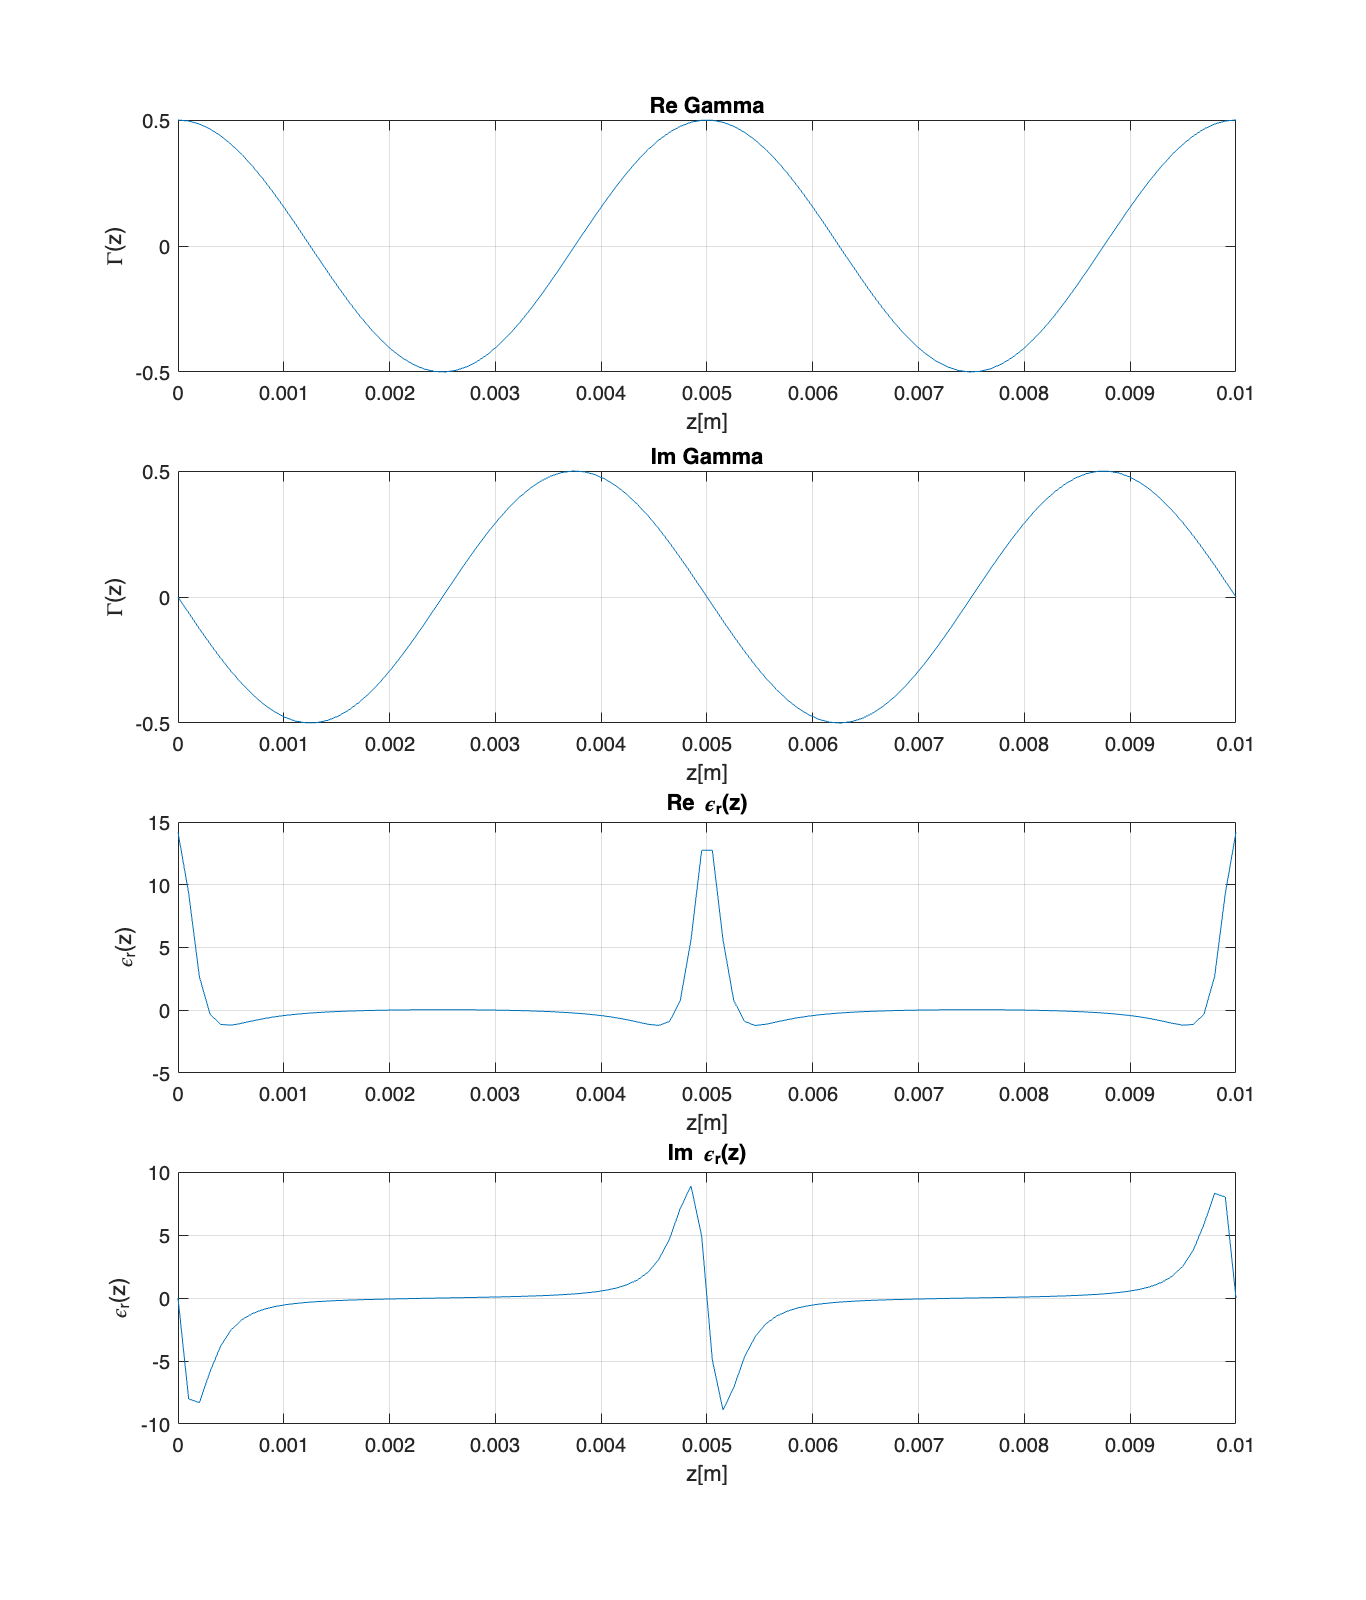


figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(4,1,1)
plot(z, real(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Re Gamma")

subplot(4,1,2)
plot(z, imag(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Im Gamma")

subplot(4,1,3)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(4,1,4)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

Tempotal change

clear Gamma dGamma
T = 1e-10;
N_T = 100;
t = linspace(0, T, N_T)

t = 1.0e-10 *

         0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949



F = omega;

Gamma = 0.5-0.5*t.*exp(-F.*1j.*t);
dGamma = -0.5*exp(-F.*1j.*t) - 0.5*(-F.*1j)*exp(-F.*1j.*t);

a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);

D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
epst = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) + I.^(-1).*D ).^(-2)

epst = 1.0e-09 *

   0.2214 + 0.0000i   0.2171 - 0.0367i   0.2047 - 0.0711i   0.1853 - 0.1011i   0.1603 - 0.1252i   0.1319 - 0.1423i   0.1019 - 0.1523i   0.0724 - 0.1553i   0.0450 - 0.1522i   0.0209 - 0.1441i   0.0008 - 0.1324i  -0.0150 - 0.1184i  -0.0265 - 0.1034i  -0.0341 - 0.0884i  -0.0384 - 0.0742i  -0.0400 - 0.0612i  -0.0396 - 0.0498i  -0.0377 - 0.0400i  -0.0349 - 0.0319i  -0.0316 - 0.0254i  -0.0281 - 0.0202i  -0.0247 - 0.0161i  -0.0214 - 0.0129i  -0.0184 - 0.0105i  -0.0157 - 0.0087i  -0.0133 - 0.0073i  -0.0112 - 0.0063i  -0.0094 - 0.0055i  -0.0078 - 0.0049i  -0.0065 - 0.0044i  -0.0053 - 0.0040i  -0.0043 - 0.0037i  -0.0035 - 0.0034i  -0.0028 - 0.0032i  -0.0021 - 0.0030i  -0.0016 - 0.0028i  -0.0012 - 0.0026i  -0.0008 - 0.0024i  -0.0004 - 0.0022i  -0.0001 - 0.0020i   0.0001 - 0.0018i   0.0004 - 0.0016i   0.0005 - 0.0014i   0.0007 - 0.0012i   0.0008 - 0.0010i   0.0009 - 0.0009i   0.0010 - 0.0007i   0.0011 - 0.0005i   0.0011 - 0.0003i   0.0011 - 0.0001i


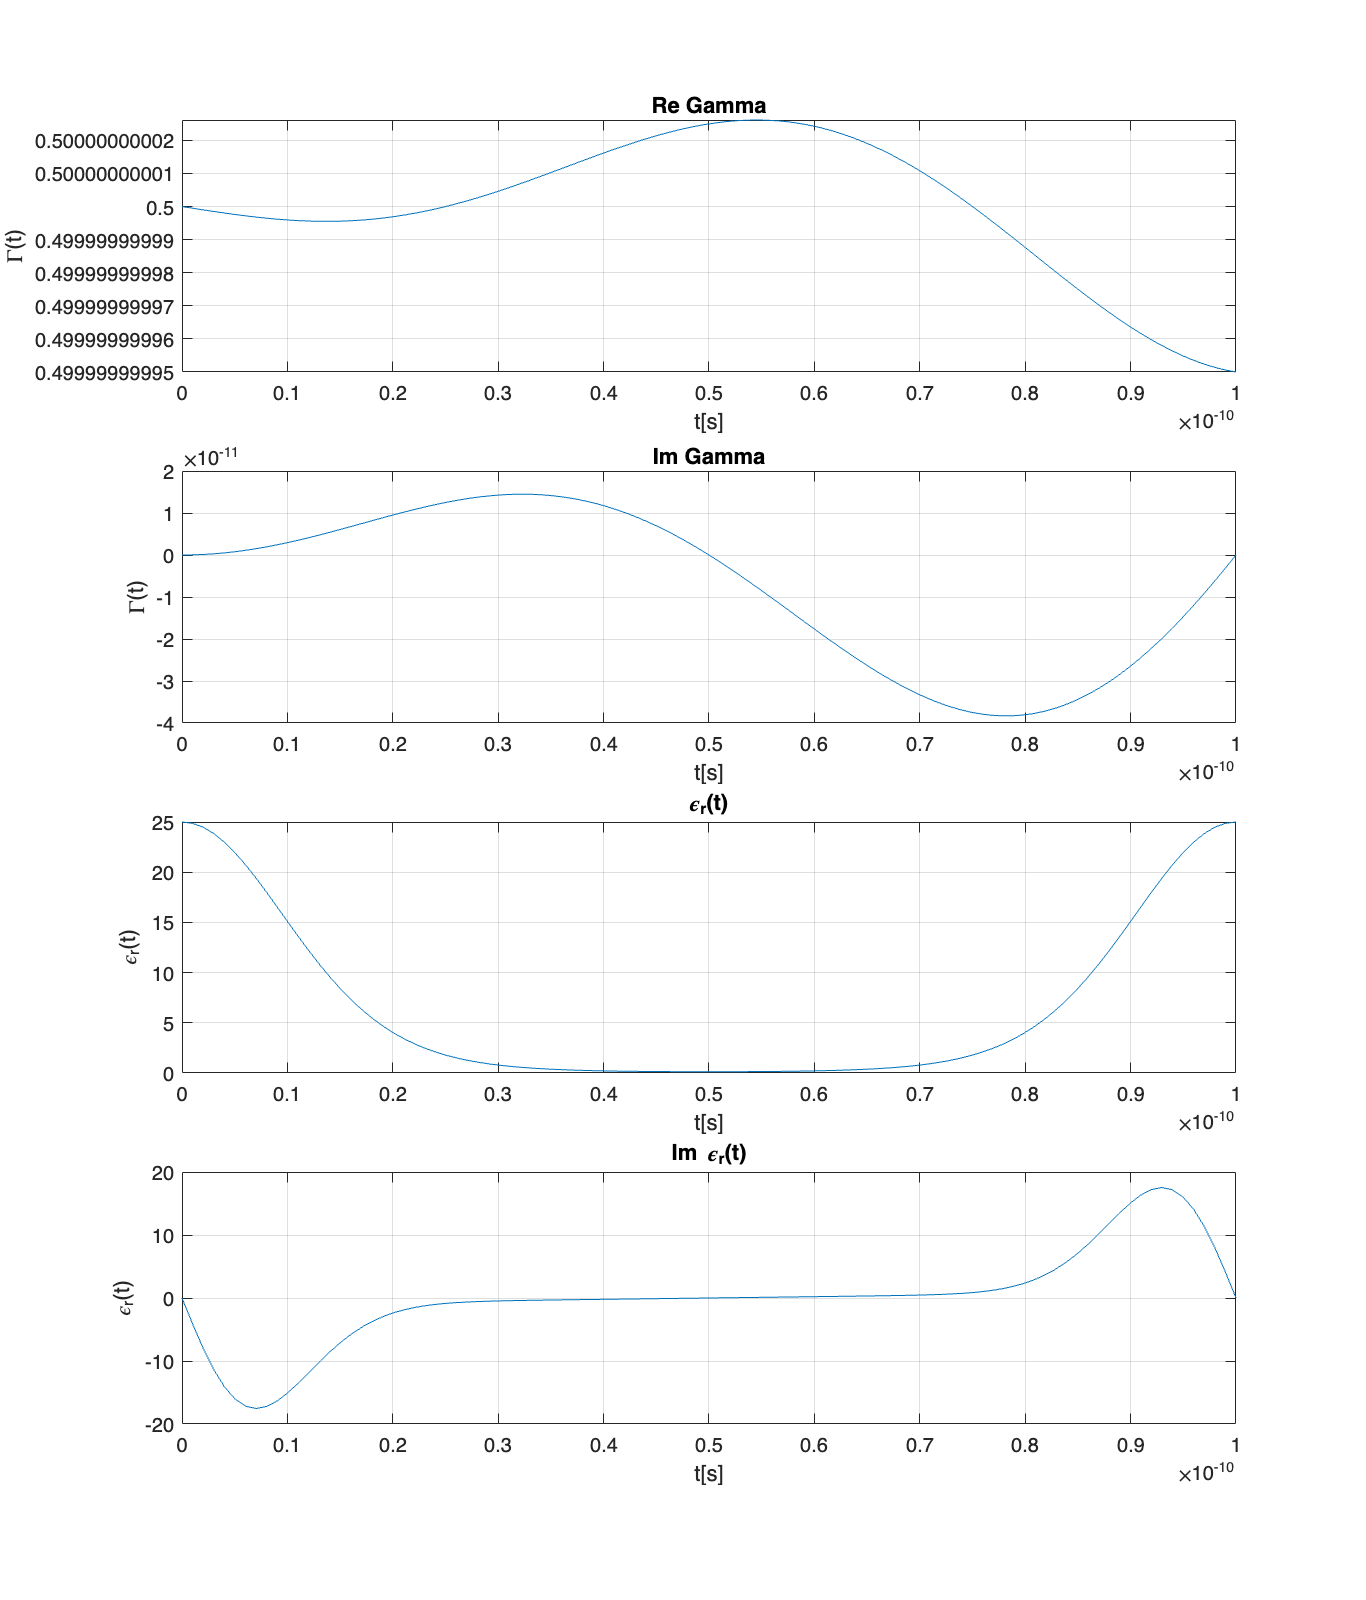


figure2=figure('Position', [100, 100, 1024, 1200]);
subplot(4,1,1)
plot(t, real(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Re Gamma")

subplot(4,1,2)
plot(t, imag(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Im Gamma")

subplot(4,1,3)
plot(t, abs(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("\epsilon_r(t)")
subplot(4,1,4)
plot(t, imag(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("Im \epsilon_r(t)")